% №1
P = [1, -3.55, 5.1, -3.1]

P =     1.0000   -3.5500    5.1000   -3.1000


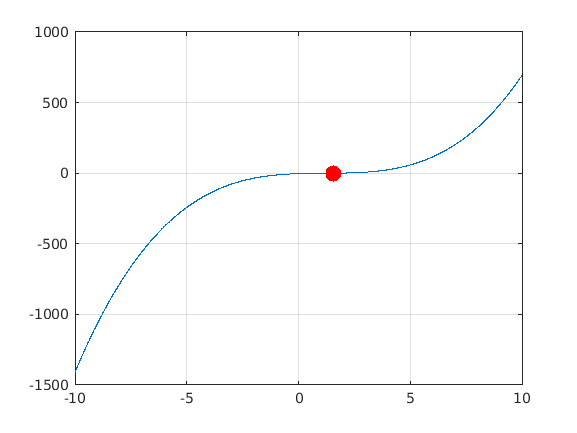

x = -10:0.01:10;
F = polyval(P,x);
plot(x, F);
grid on;
hold on;
a = roots(P);
for i = 1:length(a);
    if isreal(a(i)) == true
        plot(a(i), polyval(P,a(i)),'.', 'MarkerSize', 40, "color", "red");
    hold on;
    end
end
hold off;

% #4.1
v = [1, -2, 6, -10, 16]; a = 4;
n = v(1);
for i = 2: length(v)
    n = a*n+v(i)
end

n = 2

n = 14

n = 46

n = 200

b = polyval(v,a);
test_1=false;
if n==b
    test_1=true;
end
v1 =polyder(v);
n = v1(1)

n = 4

for i = 2: length(v1)
    n = a*n+v1(i)
end

n = 10

n = 52

n = 198

b = polyval(v1,a);
test_2=false;
if n==b
    test_2=true;
end

% #4.2
v = [1, 1+2i, 0, -1-3i, 0, 7]; a = -2-i;
n = v(1);
for i = 2: length(v)
    n = a*n+v(i)
end

n = -5.0000 + 2.0000i

n = 30.0000 - 12.0000i

n = -1.8100e+02 + 6.9000e+01i

n = 1.0860e+03 - 4.1400e+02i

n = -6.5090e+03 + 2.4840e+03i

b = polyval(v,a);
test_1=false;
if n==b
    test_1=true;
end
v1 =polyder(v);
n = v1(1)

n = 5

for i = 2: length(v1)
    n = a*n+v1(i)
end

n = -26.0000 + 8.0000i

n = 1.5600e+02 - 4.8000e+01i

n = -9.3800e+02 + 2.8200e+02i

n = 5.6280e+03 - 1.6920e+03i

b = polyval(v1,a);
test_2=false;
if n==b
    test_2=true;
end

% #3
v = [2, -3, 4, -5, 6]; u = [1, -3, 1];
[q, r] = deconv(v, u);
disp(q);

     2     3    11



v = [1, -3, -1, -1]; u = [3, -2, 1];
[q, r] = deconv(v, u);
disp(q);

    0.3333   -0.7778



% №5
n = 6;
v = [1, zeros(1, n-2), -n, 0, n, zeros(1, n-2), -1]

v =      1     0     0     0     0    -6     0     6     0     0     0     0    -1


a = roots(v);
count = 0;
for i = 1:length(a)
    for j = i+1:length(a)
        if (real(a(i)) == real(a(j)) && imag(a(i)) == imag(a(i))) 
            count = count+1; 
        end
    end
    if (count == 1)
        disp(a(i));
    end
    count = 0;
end

   0.4231 + 1.4651i

  -1.0843 + 0.9521i

   1.0000 + 0.0000i

  -0.5207 + 0.4573i

   0.1819 + 0.6300i



% #6.1
v = [1, 0, 0];
u = poly([1, -2, -3]);
r = residue(v, u);
disp(r);

    2.2500
   -1.3333
    0.0833



%6.2
v = [1, 3];
u = poly([1, i, -i]);
r = residue(v, u);
disp(r);

    0.0568
   -0.0288
   -0.0280



%6.3
v = [1, 0, 0];
u = poly([1, i, -i, -1]);
r = residue(v, u);
disp(r);

    0.0420
   -0.0420
    0.0035
   -0.0035



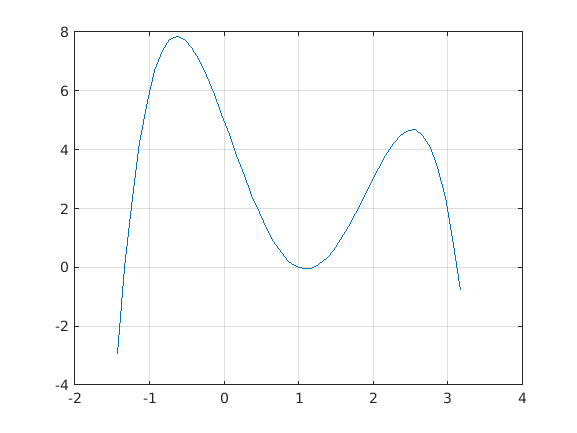

%№7.2
X = vander([-1, 0, 1, 2, 3]);
y = [6,5,0,3,2]';
a = X^-1*y;
r = roots(a);
obl = min(r)-0.1:0.1:max(r)+0.1;
plot(obl, polyval(a, obl));
grid on;

% #7.1
n = 4;
x = zeros(1, n);
y = zeros(n, 1);
for i = 1:n
    x(i) = i;
    y(i) = 1/i;
end
X = vander(x);
a = X^-1*y;
r = roots(a);
obl = min(r)-0.1:0.1:max(r)+0.1;

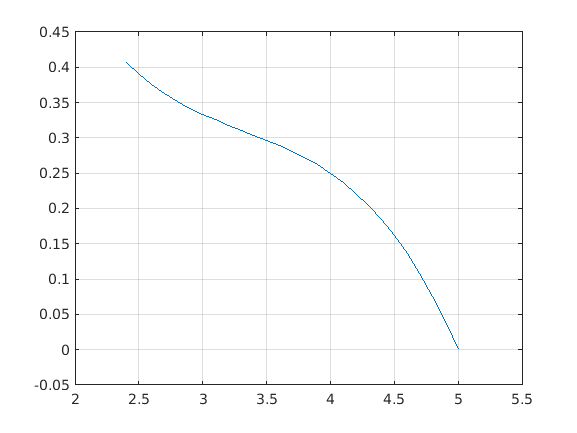

plot(obl, polyval(a, obl));
grid on;

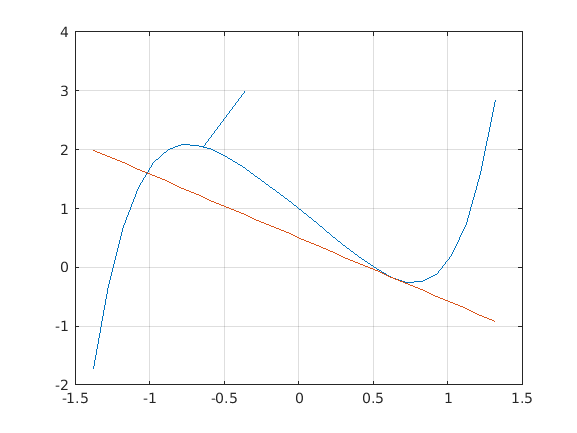

% # 2
v = [1, 0.1, 0.2, -0.2, -2, 1];
r = roots(v);
for i = 1:length(r)
        r(i) = abs(r(i));
end
obl = -max(r)-0.1:0.1:max(r)+0.1;
plot(obl, polyval(v, obl));
grid on;
hold on;
x1 = 0.5*max(r);
y1 = polyval(polyder(v), x1)*(obl-x1)+polyval(v, x1);
plot(obl, y1);
hold on;
x2 = -0.5*max(r);
f2 = -1./(polyval(polyder(v), x2));
line([x2, x2+cos(f2)], [polyval(v, x2),polyval(v, x2)+sin(f2)]);
%%plot(obl, y2);
hold off;

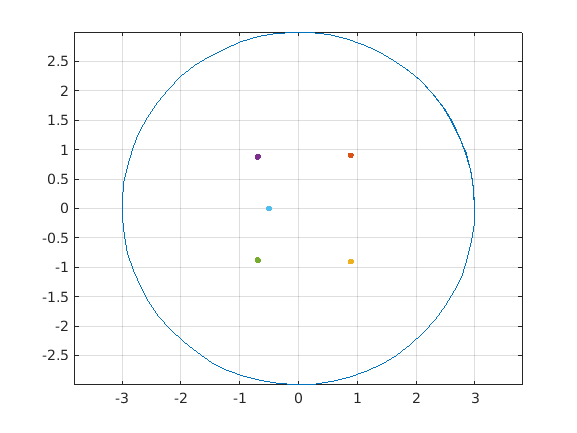


for i = 1:length(v)
        v(i) = abs(v(i));
end
R = 1 + max(v);
fi = 0:0.1:2*pi+1;
x = R*cos(fi); y = R*sin(fi);
plot(x,y);
hold on;
axis equal;
grid on;
r = roots(v);
for i = 1:length(r)
    x = real(r(i));
    y = imag(r(i));
    plot(x,y,'.', 'MarkerSize', 10)
    hold on;
end
hold off;